% Read the audio file
[y, fs] = audioread('example.wav');

% Calculate the duration of the audio sample
duration = numel(y) / fs;

% Calculate the energy of the audio sample
energy = y.^2;

% Set the threshold as a multiple of the standard deviation
thresholdFactor = 0.5; % Adjust this value as needed

threshold = baselineSilence(energy, thresholdFactor);

utterances = splitter(y, fs, threshold)

utterances = 1×3 cell array
    {85194×1 double}    {60409×1 double}    {92184×1 double}



% Print the duration
disp(['Duration of the audio sample: ' num2str(duration) ' seconds']);

Duration of the audio sample: 15.32 seconds


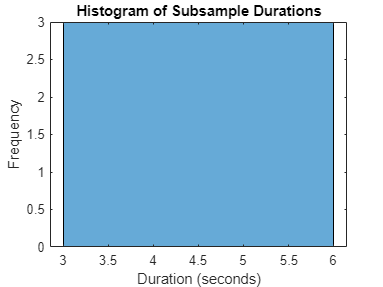

durHisto(utterances, fs)